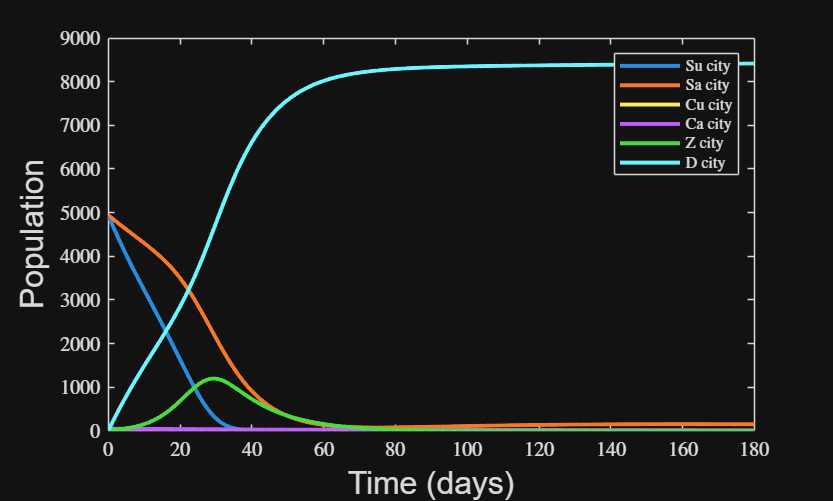

% Maze Runner Zombie Model (S–Z–D with cured + armed/unarmed + city/rural)
%
clear
close all

set(groot,'DefaultAxesTickLabelInterpreter','latex');
set(groot,'DefaultLegendInterpreter','latex');

% Parameters (you can tweak)

p_names = [ ...
    '$\beta_{Su,c}$','$\beta_{Sa,c}$', ...% city infection
    '$\beta_{Su,r}$','$\beta_{Sa,r}$', ...% rural infection
    '$\mu_{Su}$','$\mu_{Sa}$', ...        % death of susceptible
    '$\mu_{Cu}$','$\mu_{Ca}$', ...        % death of cured
    '$k_{Sa}$','$k_{Ca}$', ...            % zombie kill (armed)
    '$\theta$',...                        % decay of zombies
    '$m$', '$n$' ...                      % mix people, mix zombies
    '$j_{c}$', '$j_{r}$' ...              % corresponds to arming inflection
    '$r_{CaCu,c}$', '$r_{CaCu,r}$', ...   % Ca arms Cu in city or rural
    '$r_{CaSu,c}$', '$r_{CaSu,r}$', ...   % Ca arms Su in city or rural
    '$r_{SaCu,c}$', '$r_{SaCu,r}$', ...   % Sa arms Cu in city or rural
    '$r_{SaCu,c}$', '$r_{SaCu,r}$', ...   % Sa arms Su in city or rural
];

% - Armed get z less: beta_Sa < beta_Su
% - City contact higher than rural
% - Armed can kill zombies
% - theta = zombie "decay"
% - m = movement/mixing rate between city<->rural (idk)
params = [ ...
    0.55, 0.12, ...       % betas city  (slower spread; armed/cured-armed much safer)
    0.28, 0.07, ...       % betas rural (even slower)
    0.03, 0.004, ...      % mus cured (armed << unarmed)
    0.03, 0.004, ...      % mus susceptible (armed << unarmed)
    0.18, 0.12, ...       % k_Sa, k_Ca (armed kills zombies)
    0.010, ...            % theta (decay)
    0.01, .005, ...       % m (people mixing), n (n<m zombie mixing)
    100, 100, ...       % critical inflection time that changes arming behavior
    .00000005, .00000005, ...         % Notice 
    0.01, 0.0025, ...     % 
    0.01, 0.0025, ...     %
    0.6, 0.15             % 
];



%INITIAL START
% Initial conditions idk
N_city  = 10000;   % city population
N_rural = 1000;    % rural population

cure_frac = 0.01;   % 1% cured

% Armed access differs by area
armed_city  = 0.5; % 40% armed in city ???
armed_rural = 0.3; % 10% armed in rural ??

% Initial zombies (idk)
Z0_city  = 20;
Z0_rural = 5;

% Initial dead idk
D0_city  = 0;
D0_rural = 0;

%INITIAL END

% Split cured vs susceptible at t=0 (excluding initial zombies)
alive0_city  = N_city  - Z0_city  - D0_city;
alive0_rural = N_rural - Z0_rural - D0_rural;

C0_city  = cure_frac * alive0_city;
S0_city  = alive0_city - C0_city;

C0_rural = cure_frac * alive0_rural;
S0_rural = alive0_rural - C0_rural;

% Split armed/unarmed within each group
Ca0_city = armed_city  * C0_city;   Cu0_city = C0_city - Ca0_city;
Sa0_city = armed_city  * S0_city;   Su0_city = S0_city - Sa0_city;

Ca0_rural = armed_rural * C0_rural; Cu0_rural = C0_rural - Ca0_rural;
Sa0_rural = armed_rural * S0_rural; Su0_rural = S0_rural - Sa0_rural;


% City:  [Su_c; Sa_c; Cu_c; Ca_c; Z_c; D_c;
% Rural:  Su_r; Sa_r; Cu_r; Ca_r; Z_r; D_r]
Y = [Su0_city;Sa0_city;Cu0_city;Ca0_city;Z0_city;D0_city; ...
     Su0_rural;Sa0_rural;Cu0_rural;Ca0_rural;Z0_rural;D0_rural];


% ODE
tspan = linspace(0, 180, 1000); % 100 days, 1000 points
[t,y_solution] = ode45(@(t,Y) rhs(t,Y,params), tspan, Y);


% Plot
figure(1)

% City
plot(t,y_solution(:,1), 'LineWidth',2); hold on
plot(t,y_solution(:,2), 'LineWidth',2)
plot(t,y_solution(:,3), 'LineWidth',2)
plot(t,y_solution(:,4), 'LineWidth',2)
plot(t,y_solution(:,5), 'LineWidth',2)
plot(t,y_solution(:,6), 'LineWidth',2)


legend({'Su city','Sa city','Cu city','Ca city','Z city','D city'}, 'FontSize',8)
xlabel('Time (days)', 'FontSize',16)
ylabel('Population', 'FontSize',16)

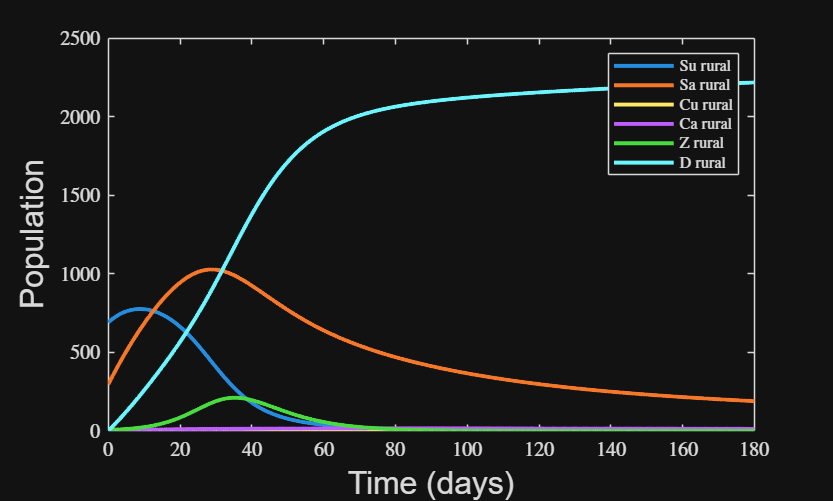


figure(2)

% Rural
plot(t,y_solution(:,7), 'LineWidth',2); hold on
plot(t,y_solution(:,8), 'LineWidth',2)
plot(t,y_solution(:,9), 'LineWidth',2)
plot(t,y_solution(:,10),'LineWidth',2)
plot(t,y_solution(:,11),'LineWidth',2)
plot(t,y_solution(:,12),'LineWidth',2)

legend({'Su rural','Sa rural','Cu rural','Ca rural','Z rural','D rural'}, 'FontSize',8)
xlabel('Time (days)', 'FontSize',16)
ylabel('Population', 'FontSize',16)



% RHS (ODE system)
function dYdt = rhs(t,Y,params) %#ok<INUSD>
    dYdt = zeros(12,1);

    % state
    Su_c = Y(1);  Sa_c = Y(2);  Cu_c = Y(3);  Ca_c = Y(4);  Z_c = Y(5);  D_c = Y(6);
    Su_r = Y(7);  Sa_r = Y(8);  Cu_r = Y(9);  Ca_r = Y(10); Z_r = Y(11); D_r = Y(12);

    % params
    beta_Su_c = params(1);  beta_Sa_c = params(2);  % city infection
    beta_Su_r = params(3);  beta_Sa_r = params(4);  % rural infection
    mu_Su     = params(5);  mu_Sa     = params(6);  % death susceptible
    mu_Cu     = params(7);  mu_Ca     = params(8);  % death cured
    k_Sa      = params(9);  k_Ca      = params(10); % killing zombies
    theta     = params(11);                         % decay
    m         = params(12); n         = params(13); % mixing people; mixing zombies
    j_c       = params(14); j_r       = params(15); % critical zombie mass circulates arms
    r_CaCu_c  = params(16); r_CaCu_r  = params(17);
    r_CaSu_c  = params(18); r_CaSu_r  = params(19);
    r_SaCu_c  = params(20); r_CaSu_r  = params(21);
    r_SaSu_c  = params(22); r_CaSu_r  = params(23);

    % Helper totals (alive in each patch, excluding dead)
    N_c = max(Su_c + Sa_c + Cu_c + Ca_c, 1);
    N_r = max(Su_r + Sa_r + Cu_r + Ca_r, 1);

    % Infection forces 
    lambda_Su_c = beta_Su_c * Z_c / N_c;
    lambda_Sa_c = beta_Sa_c * Z_c / N_c;

    lambda_Su_r = beta_Su_r * Z_r / N_r;
    lambda_Sa_r = beta_Sa_r * Z_r / N_r;

    % Human outcomes when attacked
    % City 
    dead_Cu_c = mu_Cu * Cu_c; dead_Ca_c = mu_Ca * Ca_c; %Death C
    dead_Su_c = mu_Su * Su_c; dead_Sa_c = mu_Sa * Sa_c; %Death S
    infected_Sa_c = lambda_Sa_c * Sa_c;
    infected_Su_c = lambda_Su_c * Su_c;
     attack_Su_c = infected_Su_c + dead_Su_c;
     attack_Sa_c = lambda_Sa_c * Sa_c + mu_Sa * Sa_c;


    % Rural 
    infected_Su_r = lambda_Su_r * Su_r;
    dead_Su_r = mu_Su * Su_r;
     attack_Su_r = infected_Su_r + dead_Su_r;
    infected_Sa_r = lambda_Sa_r * Sa_r;
    dead_Sa_r = mu_Sa * Sa_r;
     attack_Sa_r = lambda_Sa_r * Sa_r + mu_Sa * Sa_r;
    dead_Cu_r = mu_Cu * Cu_r;
    dead_Ca_r = mu_Ca * Ca_r;

    % Zombies killed by armed humans
    % Armed humans reduce zombies directly.
    killZ_c = (k_Sa * Sa_c + k_Ca * Ca_c) * Z_c / N_c;
    killZ_r = (k_Sa * Sa_r + k_Ca * Ca_r) * Z_r / N_r;

    % Movement/mixing between
    move_Su_c = m*Su_r;  move_Su_r = m*Su_c;
    move_Sa_c = m*Sa_r;  move_Sa_r = m*Sa_c;
    move_Cu_c = m*Cu_r;  move_Cu_r = m*Cu_c;
    move_Ca_c = m*Ca_r;  move_Ca_r = m*Ca_c;
    move_Z_c  = m*Z_r;  move_Z_r  = m*Z_c;

    % Arming others 
    arm_CaSu_c = r_CaCu_c*Ca_c*Su_c*(1 - Z_c/j_c)*Z_c;
    arm_CaSu_cant = r_CaCu_c*(1 - Z_c/j_c)*Z_c;

    % City derivatives
    dSu_c = -attack_Su_c - move_Su_r + move_Su_c -  arm_CaSu_c;
    dSa_c = -attack_Sa_c + move_Sa_c - move_Sa_r +  arm_CaSu_c;
    dCu_c = -dead_Cu_c + move_Cu_c - move_Cu_r;
    dCa_c = -dead_Ca_c + move_Ca_c - move_Ca_r;

    dZ_c  = ...
        infected_Su_c + infected_Sa_c + ...
        - killZ_c - theta*Z_c + move_Z_c - move_Z_r;

    dD_c  = ...
        dead_Su_c + dead_Sa_c + ...
        dead_Cu_c + dead_Ca_c ... 
        + killZ_c + theta*Z_c; % dead accumulates from killed/decayed zombies too (SZD)

    % Rural derivatives
    dSu_r = -attack_Su_r + move_Su_r - move_Su_c;
    dSa_r = -attack_Sa_r + move_Sa_r - move_Sa_c;
    dCu_r = -dead_Cu_r + move_Cu_r - move_Cu_c;
    dCa_r = -dead_Ca_r + move_Ca_r - move_Ca_c;

    dZ_r  = ...
        infected_Su_r + infected_Sa_r + ...
        - killZ_r - theta*Z_r + move_Z_r - move_Z_c;

    dD_r  = ...
        dead_Su_r + dead_Sa_r + ...
        dead_Cu_r + dead_Ca_r ...
        + killZ_r + theta*Z_r;

    % Pack up
    dYdt(1)  = dSu_c;
    dYdt(2)  = dSa_c;
    dYdt(3)  = dCu_c;
    dYdt(4)  = dCa_c;
    dYdt(5)  = dZ_c;
    dYdt(6)  = dD_c;
    dYdt(7)  = dSu_r;
    dYdt(8)  = dSa_r;
    dYdt(9)  = dCu_r;
    dYdt(10) = dCa_r;
    dYdt(11) = dZ_r;
    dYdt(12) = dD_r;
end
